# Markov Chains

## Making Matrices With Matlab

Making matrices with matlab is rather straight forward, as you separate elements in the same row by a ' ' or a ',', and you separate rows by the ';'. 

For example, if we wanted to make the matrix 


$$\mathbf{A} = \pmatrix{1 & 0 & 0 \cr 0 & 0.5 & 0.5 \cr 0.1 & 0.4 & 0.5}$$


we would use the following code:

A = [1,0,0; 0,0.5,0.5; 0.1,0.4,0.5]

A =        1              0              0       
       0              1/2            1/2     
       1/10           2/5            1/2     


In fact, there is no requirement to have a square matrix, so we could make the following $2\times3$ matrix


$$\mathbf{B} = \pmatrix{0.3 & 0.3 & 0.4 \cr 0.6 & 0 & 0.4}$$


B = [0.3,0.3,0.4; 0.6,0.0,0.4]

B =        3/10           3/10           2/5     
       3/5            0              2/5     


This works for any shape matrix, but if the matrix has some special structure, then it might be easier to input it differently to take less time. For example, if we want $\mathbf{I} = \pmatrix{1.0 & 0.0 & 0.0 \cr 0.0 & 1.0 & 0.0 \cr 0.0 & 0.0 & 1.0}$

we can use the short cut of 

I = eye(3)

I =        1              0              0       
       0              1              0       
       0              0              1       


This allows us to make the $3\times3$identity matrix.

## Using Matrices to represent Markov Chains

Markov chains are a collection of states with probabilities to go to the next state. Since these are probabilities, we need to make sure that each entry of each transition is between 0 and 1, and that the total of all transitions sums to exactly 1. A matrix that has these properties are called 'stochastic'. This is what motivates the code '*isStochastic(A)*', as it checks whether a given matrix is stochastic, and can be used to represent a Markov chain.

boolean = isStochastic(A)

boolean = logical
   1


doubleBool = isDoublyStochastic(A)

doubleBool = logical
   0


#### Visualizing Markov Chains

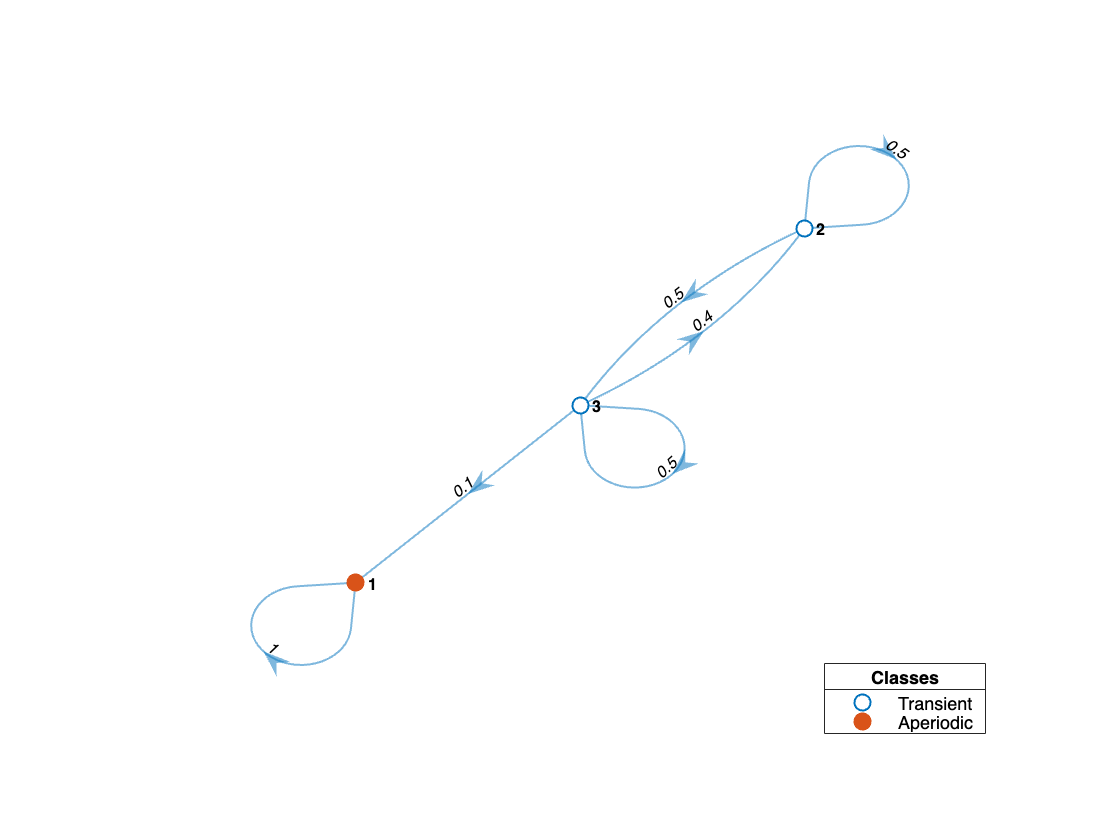

mc = dtmc(A);
figure;
graphplot(mc, 'LabelEdges',true, 'ColorNodes',true)

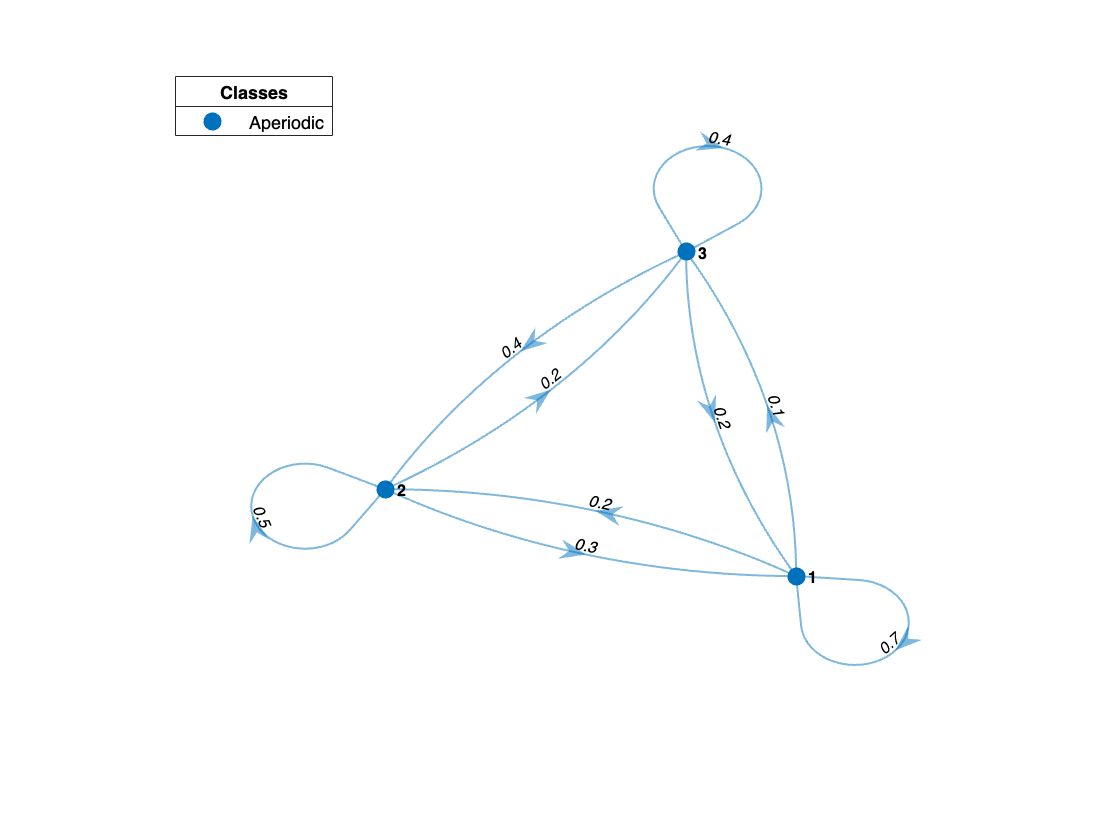

mc = dtmc(socialMobility);
figure;
graphplot(mc, 'LabelEdges',true, 'ColorNodes',true)

## Multistep Transitions

socialMobility = [0.7,0.2,0.1;0.3,0.5,0.2;0.2,0.4,0.4]

socialMobility =        7/10           1/5            1/10    
       3/10           1/2            1/5     
       1/5            2/5            2/5     


h

A2 = A^2

A2 =        1              0              0       
       1/20           9/20           1/2     
       3/20           2/5            9/20    


A2m = mpower(A,2)

A2m =        1              0              0       
       1/20           9/20           1/2     
       3/20           2/5            9/20    


## Classification of States

## Stationary Distribution

A **stationary distribution** is a distribution $$\mathbf{\pi} = (\pi_1, \pi_2,\cdots, \pi_n)$$ (where $\pi_1 + \pi_2 + \cdots +\pi_n = 1$, after all it is a distribution) such that taking one more step through the transition matrix $p$, we end up with the same distribution as before, namely $\bf\pi$. This can be represented by $\mathbf{\pi} p = \mathbf{\pi}$. We will explain this concept through 2 and 3 state Markov chains, and then generalize to a method that works for any size Markov Chain.

#### Stationary Distribution for 2- state Markov Chain 

Recall the weather chain example. We would like to write it in the stationary distribution form. 


$$\mathbf{W} = \pmatrix{0.6 & 0.4  \cr 0.2 & 0.8 }$$



$$\pmatrix{\pi_1 & \pi_2}\pmatrix{0.6 & 0.4  \cr 0.2 & 0.8 } = \pmatrix{\pi_1 & \pi_2}$$


This means we get the following system of equations:


$$0.6\pi_1 + 0.2\pi_2 = \pi_1\\
0.4\pi_1 + 0.8\pi_2 = \pi_2$$


From high school algebra, we should be able to solve this as there are 2 equations and 2 unknowns. However, we observe that $\pi_1 = 0.5 \pi_2 $, so plugging into the second equation we get $\pi_2 = \pi_2$, so this is not the way to solve it. However, we also know that since both equations become $0.4\pi_1 = 0.2\pi_2 \Rightarrow 2\pi_1= \pi_2$, and $\pi_1+\pi_2 = 1$, then $\pi_1 = \frac{1}{3}, \pi_2 = \frac{2}{3}$.

Quickly checking our solution, we arrive at 


$$\pmatrix{\pi_1 & \pi_2}\pmatrix{0.6 & 0.4 \cr 0.2 & 0.8} = \pmatrix{\frac{1}{3} & \frac{2}{3}}\pmatrix{0.6 & 0.4 \cr 0.2 & 0.8} = \pmatrix{\frac{0.6}{3} +\frac{0.4}{3} & \frac{0.4}{3} + \frac{1.6}{3}} = \pmatrix{\frac{1}{3} & \frac{2}{3}} = \pmatrix{\pi_1 & \pi_2}\$$


#### Gerealization to Stationary Distribution for 2-state Markov Chains

Now let's try to use this method to a general 2 state Markov chain, where the two states are "1" and "2". Let $a
$ be the probability of going from 1 to 2, and $b$ be the probability of going from 2 to 1. Since each row has to sum to 1, this means the general chain looks like


$$\matrix{& {\bf 1} & {\bf 2} \cr {\bf 1} & 1-a & a\cr{\bf 2} & b & 1-b}$$


Now to find the stationary distribution, we form the equations


$$\pmatrix{\pi_1 & \pi_2}\pmatrix{1-a &a  \cr b & 1-b } = \pmatrix{\pi_1 & \pi_2}$$



$$(1-a)\pi_1 + b\pi_2 = \pi_1\\
a\pi_1 + (1-b)\pi_2 = \pi_2$$


Since both equations simplify to $\pi_1 = \frac{b}{a}\pi_2$, we need to additionally inforce the $\pi_1 + \pi_2 = 1$condition to solve the systems. Using substitution, we arrive at 

$\frac{b}{a}\pi_2 + \frac{a}{a}\pi_2 = 1 \Rightarrow \pi_2 = \frac{a}{a+b}$, so $\pi_1 = \frac{b}{a+b}$.

Lastly, we check that this formula is consistent with the answer that we found for the weather chain problem. There $a = 0.4, b = 0.2$, so $\pi_1 = \frac{0.2}{0.4+0.2} = \frac{1}{3}$, and $\pi_2 = \frac{0.4}{0.4+0.2} = \frac{2}{3}$, which is consistent to what we found above.

#### Stationary Distribution for 3- state Markov Chain

Now we turn our attention to 3-state Markov chains, such as the social mobility problem.


$$0.7\pi_1 + 0.3\pi_2 + 0.2\pi_3 =\pi_1\\
0.2\pi_1 + 0.5\pi_2 + 0.4\pi_3 = \pi_2\\
0.1\pi_1+ 0.2\pi_2 + 0.4\pi_3 = \pi_3$$


But observe that if we add the equations together, since the columns come from a stochastic matrix, we get the redudant equation that $\pi_1 +\pi_2 +\pi_3 =\pi_1 +\pi_2 +\pi_3$, which will cause the system of equations to be unsolvable. So we need to change this to $\pi_1 +\pi_2 +\pi_3 =1$, since it is a probability distribution, and it must sum to 1.  This means that we get the following system of equations.


$$-0.3\pi_1 + 0.3\pi_2 + 0.2\pi_3 =0\\
0.2\pi_1 - 0.5\pi_2 + 0.4\pi_3 = 0\\
\pi_1+ \pi_2 + \pi_3 = 1$$


Now with the following 

statSocialMob = stationaryDistribution(socialMobility)

statSocialMob =       22/47          16/47           9/47    


brandPref = [0.8,0.1,0.1;0.2,0.6,0.2;0.3,0.3,0.4];
statBrandPref = stationaryDistribution(brandPref)

statBrandPref =        6/11           3/11           2/11    


#### General Stationary Distribution for $n$- state Markov Chains (advanced topic)

This code works for stochastic matrices of any size, but why? One of the main topics in Linear Algebra is that of an eigenvalue /eigenvector pair. $\mathbf{A}v= \lambda v$, where $\lambda$ is the eigenvalue and $v$ is the eigenvector. However, 

### Appendix 1: Function Codes for above

#### Checks if Matrix is a stochastic matrix

function bool = isStochastic(A)
    num_rows = size(A,1);   % Number of rows
    num_cols = size(A,2);   % Number of columns
    % Ensure A is square
    if num_cols ~= num_rows
        bool = false;
        return;
    end
    for i = 1:num_rows
        row_sum = 0;
        % Loop over columns of ith row
        for j = 1:num_cols
            % Checks for positive numbers 
            if A(i,j) < 0
                bool = false;
                return;
            else
                row_sum = row_sum + A(i,j);
            end
        end
        % Checks row sum adds to 1
        if row_sum ~= 1
            bool = false;
            return;
        end
    end
    bool = true;
end

#### Checks if Matrix is a doubly stochastic matrix

function bool = isDoublyStochastic(A)
    if (isStochastic(A) && isStochastic(A'))
        bool = true;
    else 
        bool = false;
    end
end


#### Solves the Stationary distribution of a matrix

function statDist = stationaryDistribution(A)
    n = size(A,1);
    A = A - eye(n); % pi P = pi I so pi (P-I) = 0
    A(:,n) = ones(1,n); % rewriting the last equation as pi = 1
    lastRow = zeros(1,n);
    lastRow(n) = 1;
    % Solves (0,0,...,0,1)P^{-1} in a more efficient way
    statDist = lastRow/A;
end
